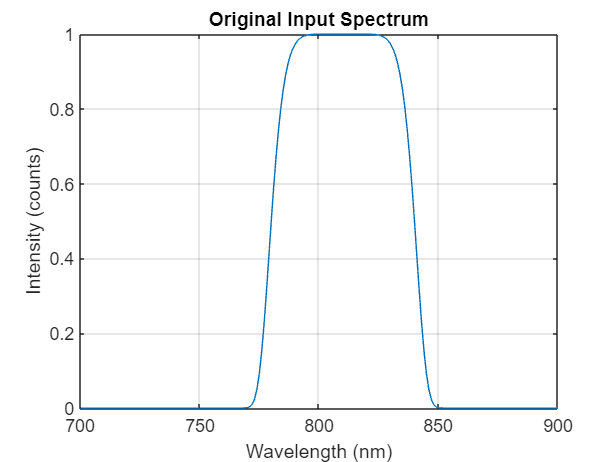

% =========================================================================
% Purpose
%   - Load a spectrum I(λ) (wavelength in nm), remove DC/background,
%   - Convert to frequency domain E(f) and compute the time-domain intensity
%     via IFFT (transform-limited pulse),
%   - FFT back to frequency to compare reconstructed spectrum to input,
%   - Fit the input and reconstructed spectra with a Super-Gaussian,
%   - Fit the time-domain intensity with a Gaussian to estimate TL pulse width,
%   - Save spectra and time traces to CSV-style .txt files (with headers+units).
%
% Inputs
%   filename : text file with two columns
%              column 1 = wavelength (nm unless the "meter→nm gate" below is set)
%              column 2 = intensity (counts or arb. units)
%
% Outputs (written to disk)
%   <name>_BKCorrectedSpectrumData.txt   : wavelength [nm], normalized intensity [arb]
%   <name>_IFFT_TimeProfile.txt          : time [fs],  normalized intensity [arb]
%   <name>_IFFTProfile.txt               : time [ps],  normalized intensity [arb], windowed to [0, 5 ps]
%
% Key conventions & units
%   c : speed of light [m/s]
%   wavelength : nm  (converted from meters only if you flip the gate below)
%   frequency  : Hz  (f = c / λ, with λ in meters)
%   time axis  : seconds (plots sometimes show fs)
%   E ∝ sqrt(I)      (uses field amplitude magnitude = sqrt(normalized intensity))
%
% Important assumptions / caveats
%   1) The IFFT assumes a uniformly sampled frequency grid. We interpolate |E(f)|
%      onto an even, linearly spaced frequency vector.
%   2) Only the magnitude |E(f)| is used (no spectral phase). Result is a
%      transform-limited estimate; E(t) may be complex.
%   3) Background subtraction: intensity below (bk_mean + 2·bk_std) is zeroed.
% =========================================================================

%% Initialization
close all;
clear;
warning('off', 'all');

% Set default font properties for all figures
set(groot, 'defaultAxesFontName', 'Helvetica');
set(groot, 'defaultTextFontName', 'Helvetica');
set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultTextFontSize', 12);

%% Constants
c = 299792458; % Speed of light in vacuum (m/s)

%% Load Data
filename = '131900_average spectrum.txt';

% Use fileparts to separate out the parts of the file path
[~, name, ~] = fileparts(filename);
data = load(filename);

% If the unit of the wavelength of the raw data is meter,
% set the "if false" below to "if true" to convert meters → nm.
if false
    wavelength = data(:, 1) .* 1e9;   % meters → nm
else
    wavelength = data(:, 1);          % already nm
end

intensity = data(:, 2);

% Quick look at the raw spectrum
figure
plot(wavelength, intensity)
xlabel('Wavelength (nm)');
ylabel('Intensity (counts)');
title('Original Input Spectrum');
grid on;

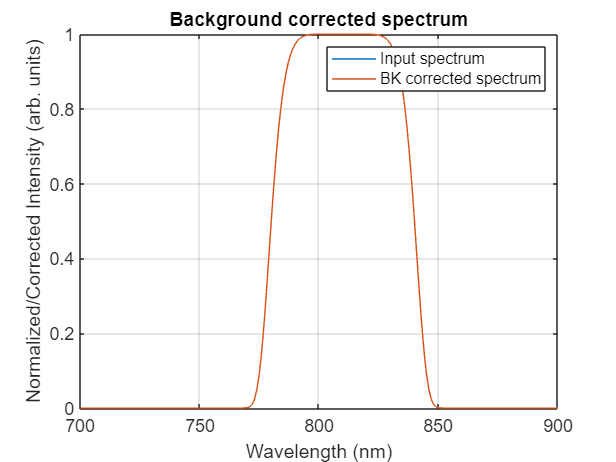

% xlim([700, 900]);

%% Background corrected spectrum
% Calculate background noise using a window [700, 750] nm
bk_indices = wavelength >= 700 & wavelength <= 750;
bk_mean = mean(intensity(bk_indices));
bk_std = std(intensity(bk_indices));
clear bk_indices;

% Make intensity below few times bk_std as zero to filter DC signal
% while avoiding intensity < 0
bk_indices = intensity <= (bk_mean + 2*bk_std);
intensity_corr = intensity - bk_mean;
intensity_corr(bk_indices) = 0;
clear bk_indices;

figure
plot(wavelength, intensity, wavelength, intensity_corr);
legend('Input spectrum', 'BK corrected spectrum');
xlabel('Wavelength (nm)');
ylabel('Normalized/Corrected Intensity (arb. units)');
title('Background corrected spectrum');
grid on;

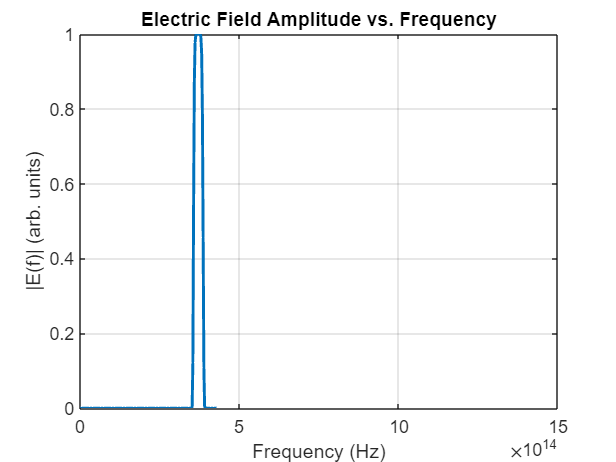


%% IFFT (from input spectrum to time domain)
% Convert to frequency domain (Hz). Since wavelength is in nm, convert to meters.
frequency = c ./ (wavelength * 1e-9);

% Normalize corrected spectrum to [0,1]
normalized_intensity = (intensity_corr) ./ max(intensity_corr);

% Electric field amplitude vs. Frequency (magnitude only, no phase)
electric_field_amplitude = abs(sqrt(normalized_intensity));

% High-resolution, evenly spaced frequency vector spanning [-f_max, f_max]
N_points = 1000 * length(frequency);
f_min = min(frequency);
f_max = max(frequency);
even_frequencies = linspace(-f_max, f_max, N_points);
extended_electric_field_amplitude = zeros(size(even_frequencies));

% Create a logical mask for the range where interpolation is valid
interp_mask = even_frequencies >= f_min & even_frequencies <= f_max;

% Interpolate measured |E(f)| onto the even grid within [f_min, f_max]
extended_electric_field_amplitude(interp_mask) = interp1( ...
    frequency, electric_field_amplitude, even_frequencies(interp_mask), 'linear');

% Time-domain analysis via IFFT (no explicit Hermitian symmetry enforced)
E_t = ifft(extended_electric_field_amplitude);

% Plot: Electric Field Amplitude vs. Frequency
figure('Name', 'E(f) - Electric Field Amplitude vs Frequency', 'NumberTitle', 'off');
plot(even_frequencies, abs(extended_electric_field_amplitude), 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|E(f)| (arb. units)');
title('Electric Field Amplitude vs. Frequency');
grid on;
xlim([0, 1.5e15]);

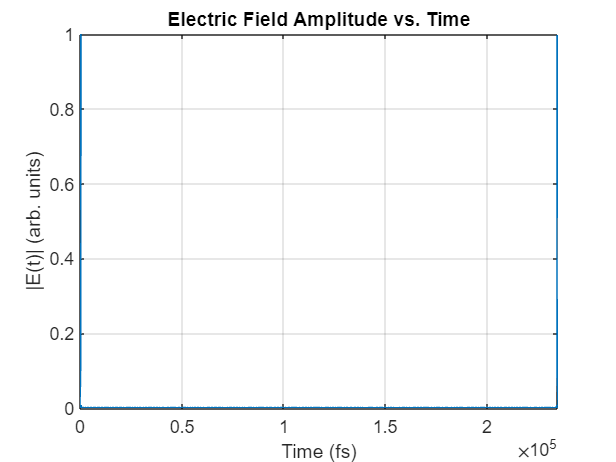


% Time axis construction (consistent with unshifted FFT convention)
delta_f = even_frequencies(2) - even_frequencies(1);
f_s = delta_f * N_points; % Sampling rate (Hz)
dt = 1 / f_s;
T_total = 1 / delta_f;
t = linspace(0, N_points, N_points) .* dt;

% Intensity in time domain
I_t = abs(E_t(1:end)).^2;
t = t(1:end);

% Normalize E_t for plotting convenience
E_t_norm = E_t / max(abs(E_t));

% Plot: Electric Field Amplitude vs. Time (fs)
figure('Name', 'E(t) - Electric Field Amplitude vs Time', 'NumberTitle', 'off');
plot(t * 1e15, abs(E_t_norm), 'LineWidth', 2); % time in fs
xlabel('Time (fs)');
ylabel('|E(t)| (arb. units)');
title('Electric Field Amplitude vs. Time');
grid on;
xlim([min(t * 1e15), max(t * 1e15)]);

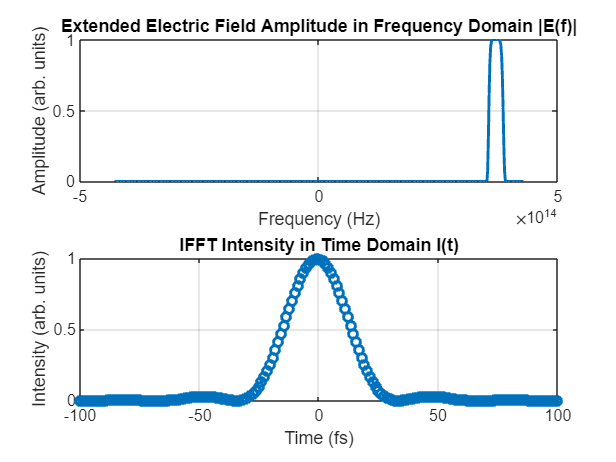


% Shift intensity in time domain so main peak centers
[max_val, max_idx] = max(I_t);
shift_amount = floor(length(I_t) / 2) - max_idx;
I_t_shifted = circshift(I_t, [0, shift_amount]);
I_t_shifted = I_t_shifted ./ max(I_t_shifted);
t_shifted = linspace(-T_total / 2, T_total / 2, length(I_t));

% There is large noise at t_shifted around 0 fs in some datasets,
% so we provide a filter that can exclude a central window. Here t_bound = 0 → keep all.
[I_t_shifted_filtered, t_shifted_filtered] = filterData(I_t_shifted, t_shifted, 0e-15);

% IFFT sanity-check plots
figure('Name', 'IFFT Check', 'NumberTitle', 'off');
subplot(2, 1, 1)
plot(even_frequencies, extended_electric_field_amplitude, '-', 'LineWidth',2);
xlabel('Frequency (Hz)');
ylabel('Amplitude (arb. units)');
title('Extended Electric Field Amplitude in Frequency Domain |E(f)|');
grid on;

subplot(2, 1, 2)
plot(t_shifted_filtered .* 1e15, I_t_shifted_filtered, 'o', 'LineWidth',2);
xlabel('Time (fs)');
ylabel('Intensity (arb. units)');
title('IFFT Intensity in Time Domain I(t)');
xlim([-100 100]);
grid on;

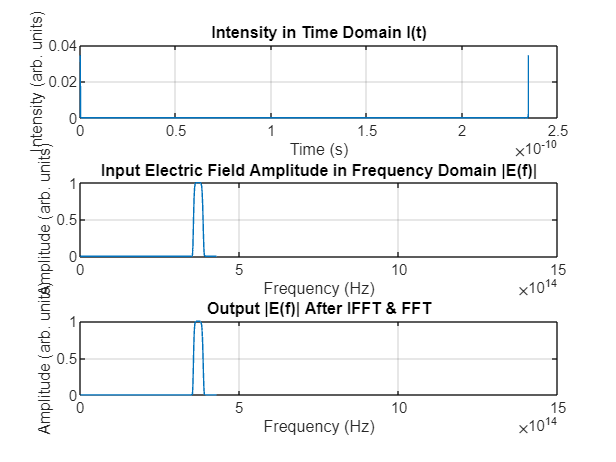


%% FFT (from time domain back to spectrum)
% Frequency domain analysis of (unshifted) time-domain field
E_f = fft(E_t);
T = max(t) - min(t);
N_FFT = length(t);
df = N_FFT / T; % nominal spacing factor
frequencies = (df / N_FFT) .* (-1/2 * N_FFT:N_FFT/2 - 1);
E_f_magnitude = abs(E_f);

% Convert to wavelength domain (positive frequencies only) and plot I(λ)
positive_frequencies = frequencies(frequencies > 0);
wavelengths_lambda = c ./ positive_frequencies; % meters
E_lambda = E_f(frequencies > 0);
I_lambda = abs(E_lambda).^2;

figure
subplot(3, 1, 1)
plot(t, abs(E_t))
xlabel('Time (s)');
ylabel('Intensity (arb. units)');
title('Intensity in Time Domain I(t)');
grid on;

subplot(3, 1, 2)
plot(even_frequencies, extended_electric_field_amplitude);
xlim([0 1.5e15])
xlabel('Frequency (Hz)');
ylabel('Amplitude (arb. units)');
title('Input Electric Field Amplitude in Frequency Domain |E(f)|');
grid on;

subplot(3, 1, 3)
plot(frequencies, E_f_magnitude)
xlim([0 1.5e15])
xlabel('Frequency (Hz)');
ylabel('Amplitude (arb. units)');
title('Output |E(f)| After IFFT & FFT');
grid on;

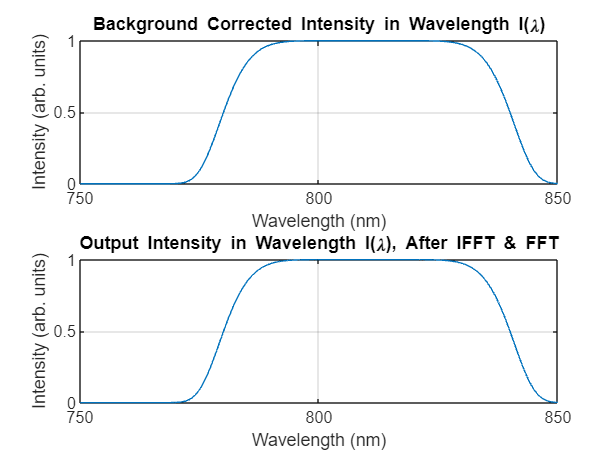


% Comparing output spectrum after IFFT & FFT with input spectrum
figure
subplot(2, 1, 1)
plot(wavelength, intensity_corr)
xlabel('Wavelength (nm)');
ylabel('Intensity (arb. units)');
title('Background Corrected Intensity in Wavelength I(\lambda)');
grid on;
xlim([750 850]);

subplot(2, 1, 2)
plot(wavelengths_lambda .* 1e9, I_lambda)
xlabel('Wavelength (nm)');
ylabel('Intensity (arb. units)');
title('Output Intensity in Wavelength I(\lambda), After IFFT & FFT');
grid on;
xlim([750 850]);

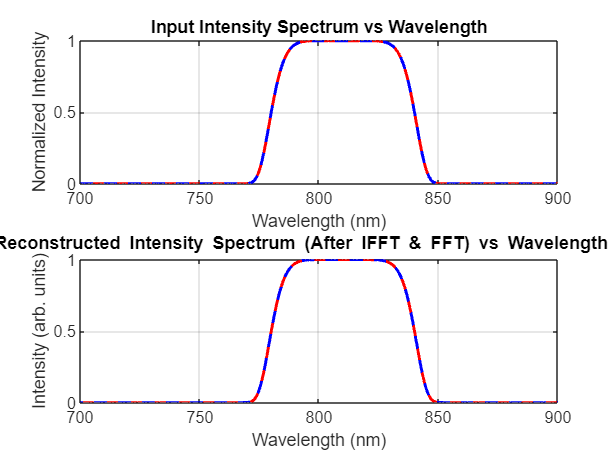


%% Super-Gaussian spectral fits (input & reconstructed)
% Define the Super-Gaussian fit type
ftype = fittype(@(A, B, C, n, D, x) superGaussian(x, A, B, C, n, D));

% Set fitting options
opts = fitoptions('Method', 'NonlinearLeastSquares');
opts.StartPoint = [1, 810, 60, 2, 0];  % [A, B(nm), C(nm), n, D]
opts.MaxIter = 100;                    % Limit number of iterations
opts.MaxFunEvals = 500;                % Optional: limit function evaluations
opts.Display = 'Off';                  % Suppress fitting display

% Super-Gaussian fitting on normalized intensity (input)
[IinFitResult, ~] = fit(wavelength, normalized_intensity, ftype, opts);

% Super-Gaussian fitting after IFFT & FFT process (reconstructed)
[Iout1FitResult, ~] = fit((wavelengths_lambda' * 1e9), I_lambda', ftype, opts);

% Combined figure for Intensity Spectrum vs Wavelength
figure('Name', 'Combined Intensity Spectrum vs Wavelength', 'NumberTitle', 'off');
subplot(2, 1, 1);
plot(wavelength, normalized_intensity, 'r-', ...
     wavelength, superGaussian(wavelength, IinFitResult.A, IinFitResult.B, IinFitResult.C, IinFitResult.n, IinFitResult.D), ...
     'b--', 'LineWidth', 2);
xlabel('Wavelength (nm)');
ylabel('Normalized Intensity');
title('Input Intensity Spectrum vs Wavelength');
grid on;
xlim([700, 900]);

subplot(2, 1, 2);
plot(wavelengths_lambda * 1e9, I_lambda, 'r-', ...
     wavelengths_lambda * 1e9, superGaussian(wavelengths_lambda * 1e9, Iout1FitResult.A, Iout1FitResult.B, Iout1FitResult.C, Iout1FitResult.n, Iout1FitResult.D), ...
     'b--', 'LineWidth', 2);
xlabel('Wavelength (nm)');
ylabel('Intensity (arb. units)');
title('Reconstructed Intensity Spectrum (After IFFT & FFT) vs Wavelength I(\lambda)');
grid on;
xlim([700, 900]);


% Save spectrum data (background-corrected, normalized)
saveSpectrumData(wavelength, normalized_intensity, [char(name), '_BKCorrectedSpectrumData.txt']);

%% The characteristics of input spectrum (print)
% The center wavelength is (unit = nm)
disp(IinFitResult.B)

  810.0000



% The bandwidth is (Super-Gaussian, unit = nm), uses ≈1.825*C for n≈2
disp(IinFitResult.C * 1.825)

   57.3167




%% The characteristics of output spectrum after IFFT & FFT (print)
% The center wavelength is (unit = nm)
disp(Iout1FitResult.B)

  810.0045



% The bandwidth is (Super-Gaussian, unit = nm), uses ≈1.825*C for n≈2
disp(Iout1FitResult.C * 1.825)

   57.3046



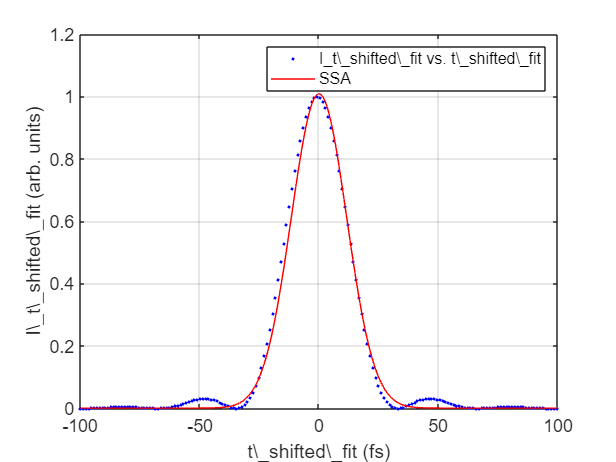


%% Use Gaussian fitting to calculate the transform limit pulse duration of the input spectrum
% Define the fitting range in time around 0:
% Fitting range of time (ps) → here t_lim = 0.1 ps (±100 fs)
t_lim = 0.1e-12; % Limit parameter for fitting

% Filter the data based on the fitting range
fittingRangeIndices = t_shifted_filtered >= -t_lim & t_shifted_filtered <= t_lim;
t_shifted_fit = t_shifted_filtered(fittingRangeIndices) * 1e15;     % (fs)
I_t_shifted_fit = I_t_shifted_filtered(fittingRangeIndices);
I_t_shifted_fit = I_t_shifted_fit ./ max(I_t_shifted_fit);

[xData, yData] = prepareCurveData( t_shifted_fit, I_t_shifted_fit );

% Set up fittype and options: I(t) = A*exp(-2*(|x/C|)^2)
ft = fittype( 'A*exp(-2*(abs((x)/C).^(2)))', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.MaxIter = 100;                   % Limit number of iterations
opts.MaxFunEvals = 500;               % Optional: limit function evaluations
opts.Lower = [0 10];
opts.Robust = 'Bisquare';
opts.StartPoint = [1.5 50];
opts.Upper = [2 100];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts ); %#ok<ASGLU>

% Plot fit with data.
figure( 'Name', 'SSA' );
h = plot( fitresult, xData, yData );
legend( h, 'I_t\_shifted\_fit vs. t\_shifted\_fit', 'SSA', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 't\_shifted\_fit (fs)', 'Interpreter', 'none' );
ylabel( 'I\_t\_shifted\_fit (arb. units)', 'Interpreter', 'none' );
grid on

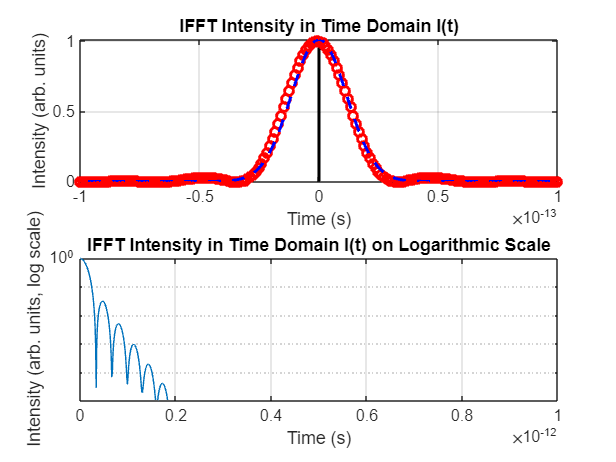


% Combined figure for Shifted Intensity in Time Domain (linear + log)
figure('Name', 'Shifted Intensity in Time Domain', 'NumberTitle', 'off');
subplot(2, 1, 1);
plot(t_shifted * 1e-15, I_t_shifted, 'k-', ...
     t_shifted_fit .* 1e-15, I_t_shifted_fit, 'ro', ...
     t_shifted, GaussianAmp(t_shifted, fitresult.A, 0, fitresult.C * 1e-15, 0), 'b--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Intensity (arb. units)');
title('IFFT Intensity in Time Domain I(t)');
xlim([-100E-15 100E-15]);
grid on;

subplot(2, 1, 2);
semilogy(t_shifted_filtered, I_t_shifted_filtered);
xlabel('Time (s)');
ylabel('Intensity (arb. units, log scale)');
title('IFFT Intensity in Time Domain I(t) on Logarithmic Scale');
grid on;
xlim([0 1e-12]);
ylim([1e-5 1]);


% Save TL pulse window (fs)
saveIFFTPulse(t_shifted_fit', I_t_shifted_fit', [char(name), '_IFFT_TimeProfile.txt']);

%% The characteristics of IFFT to time domain (print)
% The calculated transform limited pulse duration is (unit = fs)
disp(num2str(fitresult.C * sqrt(2*log(2)), '%.2f'))

27.32


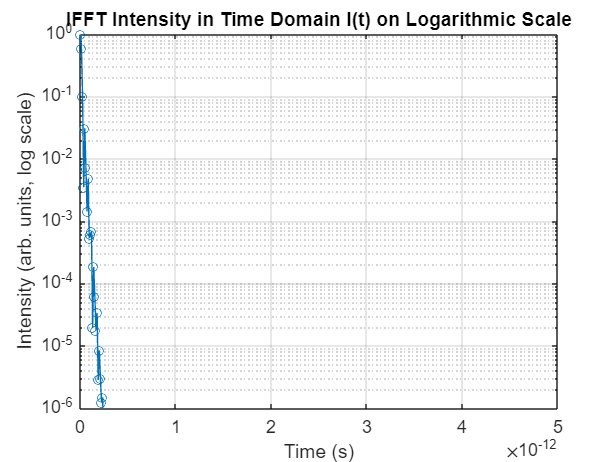


%% Save data, and down size data size to 1/1000
% Assuming t_shifted_filtered and I_t_shifted_filtered are your original arrays
N = 10; % Downsampling factor

% Downsampling by selecting every N-th element
t_shifted_filtered_downsampled = t_shifted_filtered(1:N:end)';
I_t_shifted_filtered_downsampled = I_t_shifted_filtered(1:N:end)';

% Select [0, 5 ps] range for saving and plotting (time in seconds)
[t_selected, I_selected] = selectDataInRange(t_shifted_filtered_downsampled, I_t_shifted_filtered_downsampled, 0, 5e-12);

% Save long-window IFFT on ps scale
saveIFFTData(t_selected .*1e12, I_selected, [char(name), '_IFFTProfile.txt']);

figure
semilogy(t_selected, I_selected, '-o');
xlabel('Time (s)');
ylabel('Intensity (arb. units, log scale)');
title('IFFT Intensity in Time Domain I(t) on Logarithmic Scale');
grid on;
xlim([0 5e-12]);
ylim([1e-6 1]);


%% ===========================
%            Library
%% ===========================


function y = superGaussian(x, A, B, C, n, D)
    % superGaussian:
    % A * exp(-(abs((x - B) / C).^(2*n))) + D
    y = A * exp(-(abs((x - B) / C).^(2*n))) + D;
end

function y = GaussianAmp(x, A, B, C, D)
    % GaussianAmp (intensity envelope used for plotting):
    % A * exp(-2 * (abs((x - B) / C).^(2))) + D
    y = A * exp(-2 * (abs((x - B) / C).^(2))) + D;
end

function [I_t_shifted_filtered, t_shifted_filtered] = filterData(I_t_shifted, t_shifted, t_bound)
    % filterData:
    % Removes samples with |t| <= t_bound (seconds).
    % If t_bound = 0, effectively keeps all samples except exactly t=0.
    time_lower_bound = -t_bound;
    time_upper_bound = t_bound;
    mask = t_shifted < time_lower_bound | t_shifted > time_upper_bound;
    I_t_shifted_filtered = I_t_shifted(mask);
    t_shifted_filtered = t_shifted(mask);
end

function [fitresult, gof] = createFit(t_shifted_filtered, I_t_shifted_filtered) %#ok<DEFNU>
%CREATEFIT(T_SHIFTED_FILTERED,I_T_SHIFTED_FILTERED)
%  Alternative Gaussian fit helper (not used in main flow).
%  Auto-generated by MATLAB on 18-Jan-2024 14:05:22

[xData, yData] = prepareCurveData( t_shifted_filtered, I_t_shifted_filtered );

% Set up fittype and options.
ft = fittype( 'A*exp(-2*(abs((x-B)/C).^(2)))+D', 'independent', 'x', 'dependent', 'y' );
excludedPoints = (xData < -1e-13) | (xData > 1e-13);
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.DiffMinChange = 1e-16;
opts.Display = 'Off';
opts.Lower = [0 -1e-15 10e-15 -0.1];
opts.StartPoint = [1.2 0 20e-15 0];
opts.TolFun = 1e-10;
opts.TolX = 1e-10;
opts.Upper = [2 1e-15 50e-15 0.1];
% opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts ); %#ok<NASGU>

% Plot fit with data.
figure( 'Name', 'Gaussian Amp' );
plot( fitresult, xData, yData, excludedPoints );
xlabel( 't\_shifted\_filtered', 'Interpreter', 'none' );
ylabel( 'I\_t\_shifted\_filtered', 'Interpreter', 'none' );
grid off
end

function saveSpectrumData(array1, array2, filename)
    % saveSpectrumData:
    % Writes wavelength [nm] and normalized intensity [arb] with 2-line header.
    combinedData = [array1, array2];
    mainHeaders = {'Wavelength', 'Intensity'};
    units = {'nm', 'arb. units'};
    if ~endsWith(filename, '.txt')
        filename = [filename, '.txt'];
    end
    fid = fopen(filename, 'w');
    fprintf(fid, '%s,%s\n', mainHeaders{:});
    fprintf(fid, '%s,%s\n', units{:});
    fclose(fid);
    writematrix(combinedData, filename, 'WriteMode', 'append');
end

function saveIFFTData(array1, array2, filename)
    % saveIFFTData:
    % Writes time [ps] and intensity [arb] with 2-line header.
    combinedData = [array1, array2];
    mainHeaders = {'Time', 'Intensity'};
    units = {'ps', 'arb. units'};
    if ~endsWith(filename, '.txt')
        filename = [filename, '.txt'];
    end
    fid = fopen(filename, 'w');
    fprintf(fid, '%s,%s\n', mainHeaders{:});
    fprintf(fid, '%s,%s\n', units{:});
    fclose(fid);
    writematrix(combinedData, filename, 'WriteMode', 'append');
end

function [t_selected, I_selected] = selectDataInRange(t_array, I_array, lowerBound, upperBound)
    % selectDataInRange:
    % Returns samples with lowerBound <= t <= upperBound (time in seconds).
    inRangeIndices = t_array >= lowerBound & t_array <= upperBound;
    t_selected = t_array(inRangeIndices);
    I_selected = I_array(inRangeIndices);
end

function saveIFFTPulse(array1, array2, filename)
    % saveIFFTPulse:
    % Writes time [fs] and normalized intensity [arb] with 2-line header.
    combinedData = [array1, array2];
    mainHeaders = {'Time', 'Intensity'};
    units = {'fs', 'arb. units'};
    if ~endsWith(filename, '.txt')
        filename = [filename, '.txt'];
    end
    fid = fopen(filename, 'w');
    fprintf(fid, '%s,%s\n', mainHeaders{:});
    fprintf(fid, '%s,%s\n', units{:});
    fclose(fid);
    writematrix(combinedData, filename, 'WriteMode', 'append');
end
